lqr_heli = readtable('LQR_yaw.csv')

lqr_heli = 1583×7 table
    Tiempo    U_YAW    U_PITCH    W_YAW    W_PITCH    YAW    PITCH
    ______    _____    _______    _____    _______    ___    _____

     -0.4       0         0         0         0        0       0  
    -0.38       0         0         0         0        0       0  
    -0.36       0         0         0         0        0       0  
    -0.34       0         0         0         0        0       0  
    -0.32       0         0         0         0        0       0  
     -0.3       0         0         0         0        0       0  
    -0.28       0         0         0         0        0       0  
    -0.26       0         0         0         0        0       0  
    -0.24       0         0         0         0        0       0  


polos_heli = readtable('Polos_YAW.csv')

polos_heli = 1675×7 table
    Tiempo    U_YAW    U_PITCH    W_YAW    W_PITCH    YAW    PITCH
    ______    _____    _______    _____    _______    ___    _____

     -0.4       0         0         0         0        0       0  
    -0.38       0         0         0         0        0       0  
    -0.36       0         0         0         0        0       0  
    -0.34       0         0         0         0        0       0  
    -0.32       0         0         0         0        0       0  
     -0.3       0         0         0         0        0       0  
    -0.28       0         0         0         0        0       0  
    -0.26       0         0         0         0        0       0  
    -0.24       0         0         0         0        0       0 

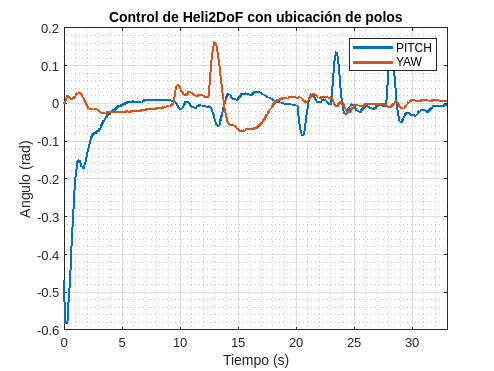


%% Cargando datos

lqr_time = lqr_heli.Tiempo;
lqr_pitch = lqr_heli.PITCH;
lqr_yaw = lqr_heli.YAW;
lqr_upitch = lqr_heli.U_PITCH;
lqr_uyaw = lqr_heli.U_YAW;


polos_time = polos_heli.Tiempo;
polos_pitch = polos_heli.PITCH;
polos_yaw = polos_heli.YAW;
polos_upitch = polos_heli.U_PITCH;
polos_uyaw = polos_heli.U_YAW;


figure;
plot(polos_time,polos_pitch,'LineWidth',2)
hold on;
plot(polos_time,polos_yaw,'LineWidth',2)
legend('PITCH','YAW')
xlabel('Tiempo (s)')
ylabel('Angulo (rad)')
xlim([0 33])
grid on;
grid minor;
title('Control de Heli2DoF con ubicación de polos')
hold off;

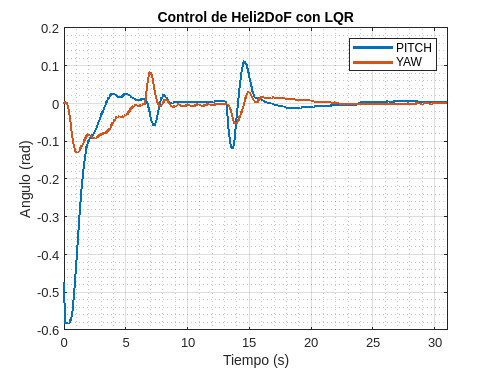



figure;
plot(lqr_time,lqr_pitch,'LineWidth',2)
hold on;
plot(lqr_time,lqr_yaw,'LineWidth',2)
legend('PITCH','YAW')
xlabel('Tiempo (s)')
ylabel('Angulo (rad)')
xlim([0 31])
grid on;
grid minor;
title('Control de Heli2DoF con LQR')
hold off;